# TP - Segway

Authors : Pierre-Henry Poret et Julien Huynh

clear vars; clc;

## Parameters

g = 9.81;
T = 0;
F = 0;
l = 1;
m = 1;
M = 5;

## Initial condition

X0 = [0; 0; pi/18; 0]; % Non linearized model
X0lin0 = [0; 0; 5 * pi/180; 0]; % Linearized around 0

## Non linear segway

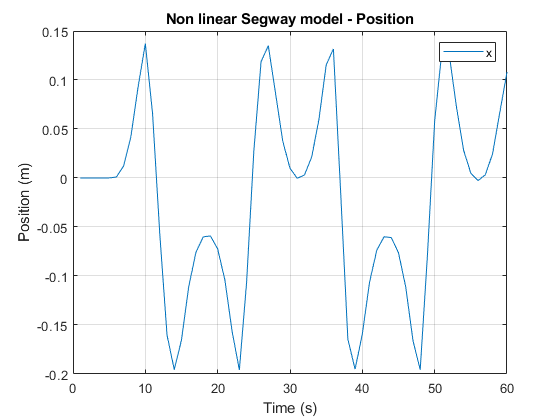

simu = sim("SegwayModel");
figure()
plot(simu.nonlinvalues(:, 1)); % Plot x
legend('x');
xlabel("Time (s)")
ylabel("Position (m)")
grid on;
title("Non linear Segway model - Position")

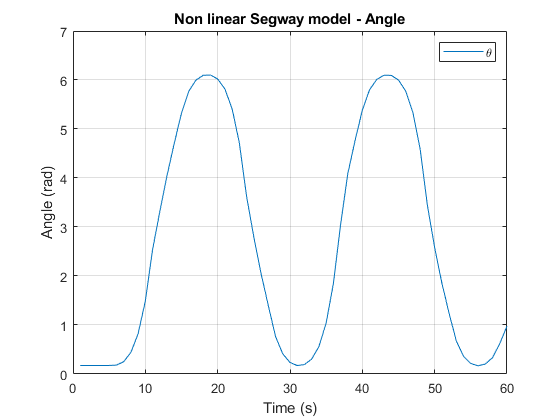

figure()
plot(simu.nonlinvalues(:, 3)); % Plot theta
xlabel("Time (s)")
ylabel("Angle (rad)")
legend('{\theta}');
grid on;
title("Non linear Segway model - Angle")

## Linearized around $\theta = 0$

A = [0 1 0 0
    0 0 m*g/M 0
    0 0 0 1
    0 0 (M+m)*g/(M*l) 0]

A =          0    1.0000         0         0
         0         0    1.9620         0
         0         0         0    1.0000
         0         0   11.7720         0


B = [0 0
    l/m 1/M
    0 0
    (m+M)/(m*M*l^2) 1/(M*l)]

B =          0         0
    1.0000    0.2000
         0         0
    1.2000    0.2000


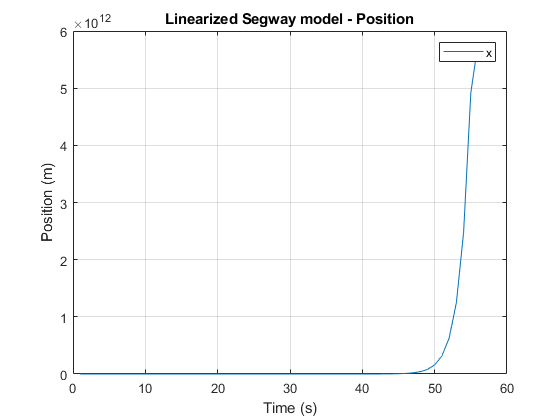

C = [1 0 0 0
     0 0 0 0
     0 0 1 0
     0 0 0 0];
D = [0 0
    0 0
    0 0
    0 0];
    
simuLin0 = sim("SegwayModelLinearized0");
figure()
plot(simuLin0.lin0values(:, 1)); % Plot x
legend('x');
xlabel("Time (s)")
ylabel("Position (m)")
grid on;
title("Linearized Segway model - Position")

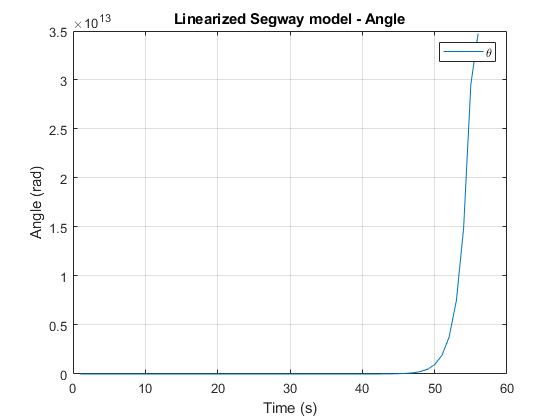

figure()
plot(simuLin0.lin0values(:, 3)); % Plot theta
xlabel("Time (s)")
ylabel("Angle (rad)")
legend('{\theta}');
grid on;
title("Linearized Segway model - Angle")

## Pole placement

p = [-1, -2, -3, -4]

p =     -1    -2    -3    -4


K = place(A, B, p)

K =   -14.4135  -19.7484   88.2390   29.6743
   87.0866  118.7500 -430.5934 -148.0540


simuLin0ctr = sim("SegwayLinearized0Controlled");